% Names of the images to be used
images_names = {
                'img1.tiff' 
                'img5.tiff' 
                'img9.tiff' 
                'img14.tiff'
               };
           

% Natural logarithm of shutter speed for each of the above images
%B = [-6 -4 -2 0];
B = [log(1/64) log(1/4) log(4) log(128)]

B =    -4.1589   -1.3863    1.3863    4.8520


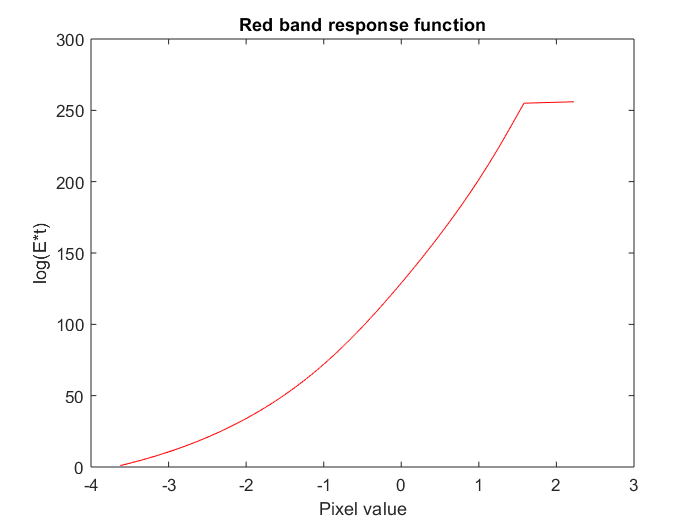


% Smoothness parameter used in equation (3). Increase it, if you have a lot
% of noise in your images.
l = 200;

% Amount of randomly selected sample points from each image. This amount
% will affect the quality of the approximation of the real response
% function. You need at least N(P-1) > (Z_max - Z_min)
% N - amount of sample points
% P - amount of images
% Assumes:
% Zmin = 0
% Zmax = 255
sample_points_amount = 100;

%Bands amount in each of the images. Usually RGB(3) or grayscale(1)
bands_amount = 3;

%% Recovering response function

img_amount = length(images_names);

% Loading images
img_container = {};
for img_number = 1:img_amount
    img_container{img_number} = imread(images_names{img_number});
end

% Create random indexes to get random points from each image
row_amount = size(img_container{1}, 1);
col_amount = size(img_container{1}, 2);
point_amount = row_amount*col_amount;
random_indexes = ceil(rand(1, sample_points_amount)*point_amount);

% Load all values from random points into Z
Z = zeros(sample_points_amount, img_amount, bands_amount);

for img_number = 1:img_amount
    for band = 1:bands_amount
        Z(:, img_number, band) = img_container{img_number}(random_indexes + (band-1)*point_amount);
    end
end

% Create response function for each band
radiance_map = zeros(256, bands_amount);
radiance_map_obj = {};

for band = 1:bands_amount
    radiance_map(:, band) = gsolve(Z(:,:,band), B, l, @weight);
    radiance_map_obj{band} = radiance_map(:, band);
end

%% Plot the response functions for each band.

figure
plot(radiance_map_obj{1}, 1:256, 'r');
title('Red band response function');
xlabel('Pixel value');
ylabel('log(E*t)');

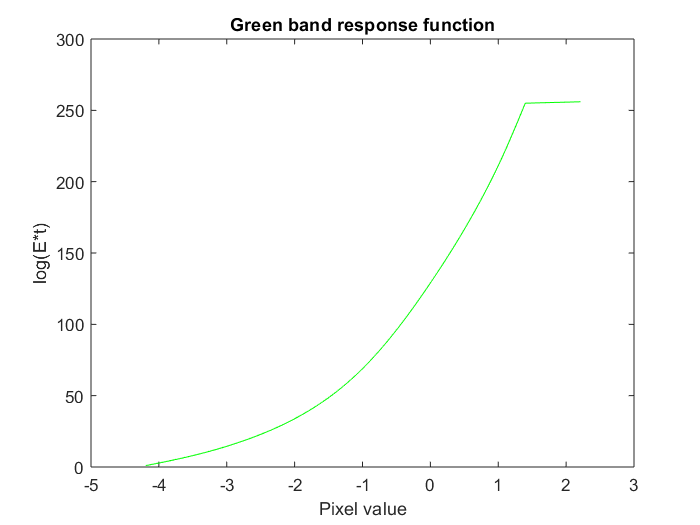


figure
plot(radiance_map_obj{2}, 1:256, 'g');
title('Green band response function');
xlabel('Pixel value');
ylabel('log(E*t)');

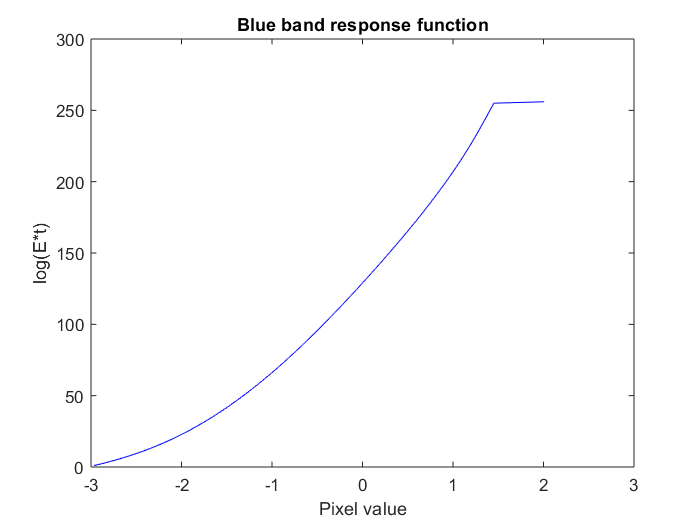


figure
plot(radiance_map_obj{3}, 1:256, 'b');
title('Blue band response function');
xlabel('Pixel value');
ylabel('log(E*t)');

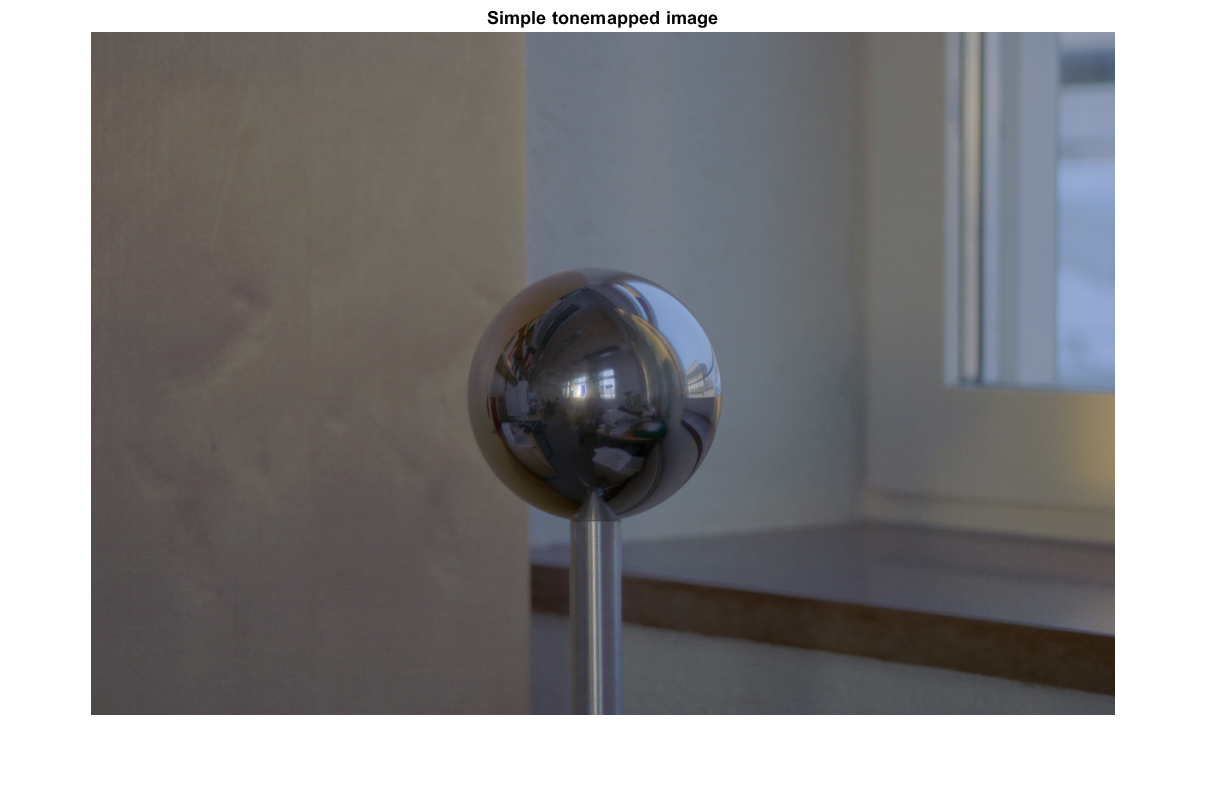

%% Getting the actual radiance values of the scene.
% The most time consuming part

% Equation (6) from the debevec paper.
% This equation is used to get the natural logarithm of radiance values
% on the scene and to get rid of artifacts

%Corner case: ones() matrix to avoid dividing by 0
denominator = ones(row_amount, col_amount, bands_amount);
numerator = zeros(row_amount, col_amount, bands_amount);
for img_number = 1:img_amount
    zij = double(img_container{img_number});
    g_zij = zij;
    for band = 1:bands_amount
        g_zij(:,:,band) = radiance_map_obj{band}(zij(:, :, band)+1);
    end
    g_zij = g_zij - B(img_number);
    wij = double( arrayfun(@weight, zij) );
    numerator = numerator + wij.*g_zij;
    denominator = denominator + wij;
end

% Natural logarithm of radiance values of image.
final_image = numerator ./ denominator;

%r_band = final_image(:,:,1);
%final_image(isnan(final_image)) = 0;

%% Tone mapping

% The naive tone mapping algorithm
% Eliminate all negative numbers by shifting them to the positive side and then divide each element by max value in current band
for band = 1:bands_amount
    band_max = max( max(final_image(:, :, band)) );
    band_min = min( min(final_image(:, :, band)) );
    final_image(:, :, band) = ( final_image(:, :, band) + abs(band_min) ) / ( band_max + abs(band_min) );
end

tone_mapped_img_original = im2uint8(final_image);

figure, imshow(tone_mapped_img_original);
title('Simple tonemapped image');

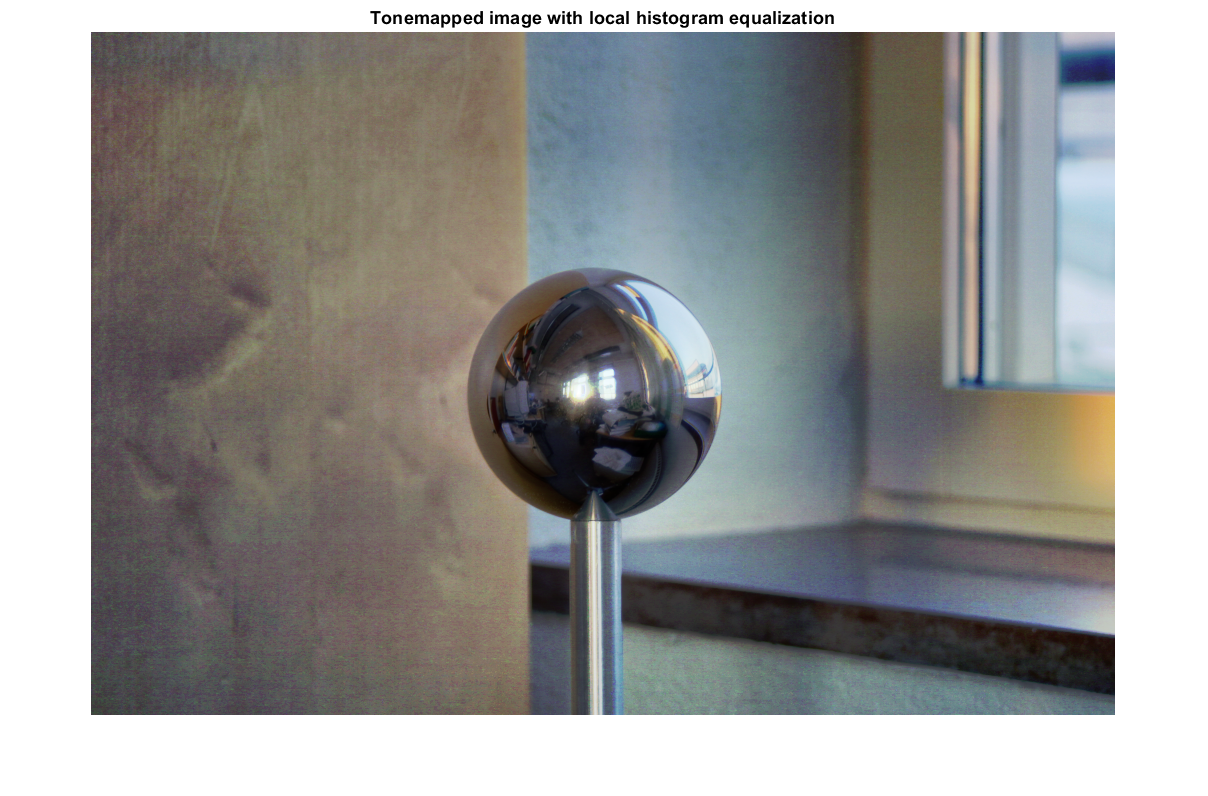


%% Apply Local histogram equalization to enhance contrast

for band = 1:3
    tone_mapped_img_hist_eq(:, :, band) = adapthisteq(tone_mapped_img_original(:, :, band), 'NumTiles', [3 3]);
end

figure, imshow(tone_mapped_img_hist_eq);
title('Tonemapped image with local histogram equalization');